## Introduction

In this scrip, we test the function 'fitoptions('Method','LowessFit')' 

## Import data

load('C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\MSDData4Quan_20210905\MSD_p77_5s_All.mat')

## Test for lowess

T=1:length(MSD_p77_5s_All.MSD_PP);
f_x=fit(T',MSD_p77_5s_All.MSD_PP(:,1),'poly9')

f_x =      Linear model Poly9:
     f_x(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =   1.147e-10  (-7.988e-12, 2.374e-10)
       p2 =   -6.13e-08  (-1.31e-07, 8.358e-09)
       p3 =   1.368e-05  (-2.943e-06, 3.031e-05)
       p4 =   -0.001662  (-0.003829, 0.0005055)
       p5 =      0.1199  (-0.04776, 0.2876)
       p6 =      -5.289  (-13.13, 2.555)
       p7 =         142  (-74.03, 358.1)
       p8 =       -2296  (-5547, 954.6)
       p9 =    2.31e+04  (279.4, 4.592e+04)
       p10 =   3.648e+04  (-1.63e+04, 8.926e+04)

f_y=fit(T',MSD_p77_5s_All.MSD_PP(:,2),'poly9')

f_y =      Linear model Poly9:
     f_y(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =  -1.458e-10  (-2.544e-10, -3.712e-11)
       p2 =    8.22e-08  (2.049e-08, 1.439e-07)
       p3 =  -1.917e-05  (-3.39e-05, -4.445e-06)
       p4 =     0.00239  (0.0004701, 0.00431)
       p5 =     -0.1714  (-0.32, -0.02288)
       p6 =        7.08  (0.1324, 14.03)
       p7 =      -157.1  (-348.5, 34.25)
       p8 =        1468  (-1411, 4348)
       p9 =        2381  (-1.784e+04, 2.26e+04)
       p10 =   6.282e+04  (1.607e+04, 1.096e+05)

f_z=fit(T',MSD_p77_5s_All.MSD_PP(:,3),'poly9')

f_z =      Linear model Poly9:
     f_z(x) = p1*x^9 + p2*x^8 + p3*x^7 + p4*x^6 + 
                    p5*x^5 + p6*x^4 + p7*x^3 + p8*x^2 + p9*x + p10
     Coefficients (with 95% confidence bounds):
       p1 =  -5.033e-10  (-7.974e-10, -2.091e-10)
       p2 =   2.607e-07  (9.365e-08, 4.277e-07)
       p3 =  -5.612e-05  (-9.599e-05, -1.625e-05)
       p4 =    0.006497  (0.0013, 0.01169)
       p5 =     -0.4368  (-0.8389, -0.03467)
       p6 =       17.14  (-1.665, 35.95)
       p7 =      -371.2  (-889.2, 146.8)
       p8 =        3690  (-4105, 1.148e+04)
       p9 =       -3506  (-5.823e+04, 5.122e+04)
       p10 =   1.749e+05  (4.831e+04, 3.014e+05)

## Figure show

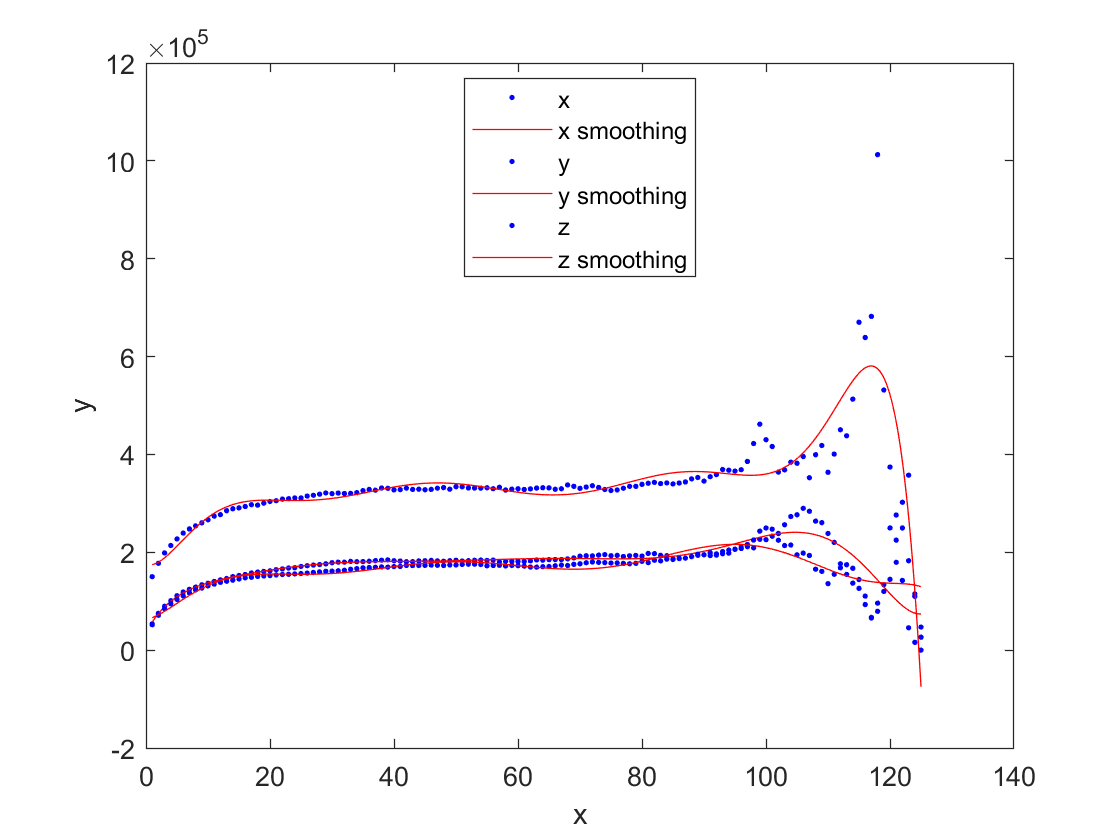

figure
plot(f_x,T',MSD_p77_5s_All.MSD_PP(:,1))
hold on
plot(f_y,T',MSD_p77_5s_All.MSD_PP(:,2))
plot(f_z,T',MSD_p77_5s_All.MSD_PP(:,3))
legend('x','x smoothing','y','y smoothing','z','z smoothing','Location',"best")